clear

x = [0:25:400];      %first half of the piecewise function
y1 = 15*x+25

y1 =           25         400         775        1150        1525        1900        2275        2650        3025        3400        3775        4150        4525        4900        5275        5650        6025


y2 = 12*x+40

y2 =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640        3940        4240        4540        4840



plot(x,y1)
title("Solar Billing Plans")
xlabel("Energy Usage (Watts)");
ylabel("Cost ($)");
hold on;

plot(x,y2)
hold on;


x = [400:25:800];     %second half of the piecewise function.
y1 = 15*x+25             %stays the same

y1 =         6025        6400        6775        7150        7525        7900        8275        8650        9025        9400        9775       10150       10525       10900       11275       11650       12025


y2 = 14*x-760            %changes 

y2 =         4840        5190        5540        5890        6240        6590        6940        7290        7640        7990        8340        8690        9040        9390        9740       10090       10440


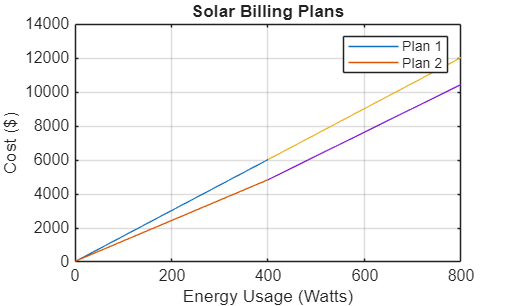


plot(x,y1)
hold on;
plot(x,y2)
hold off;

grid on;

legend('Plan 1', 'Plan 2');  % Add a legend to differentiate the two plans



usage = (0:5:60)';          % 12 rows

bill_y1 = 15*usage + 25;
bill_y2 = 12*usage + 40;

T = table(usage, bill_y1, bill_y2, ...
    'VariableNames', {'Usage_W', 'Plan1_Cost_$', 'Plan2_Cost_$'});

disp(T);

    Usage_W    Plan1_Cost_$    Plan2_Cost_$
    _______    ____________    ____________

       0            25              40     
       5           100             100     
      10           175             160     
      15           250             220     
      20           325             280     
      25           400             340     
      30           475             400     
      35           550             460     
      40           625             520     
      45           700             580     
      50           775             640     
      55           850             700     
      60           925             760     




% We can see on the table that the two plans have the same cost ($100) when
%they use 5 watts of energy. 

% I recomend that anyone should use the second plan, because it will always
% be a lower cost than the first plan after 5 watts of energy is used. 
